# **INTRODUCCIÓN A LA CUANTIFICACIÓN ESCALAR Y VECTORIAL**

[Afonso_8kHz, fs] = audioread('Afonso_8khz.wav');
[Gala_8kHz, fs] = audioread('Gala_8khz.wav');


## **TAREA 2: RELACIÓN SEÑAL-RUIDO DE CUANTIFICACIÓN**

Para el fichero Gala_8kHz.wav, con qmidriser() y qmidtread() de la tarea 1 con xsc=1:

- Obtened la SNR global, la SNR segmental y SNR por tramas. Representad junto a la señal original de forma análoga a “Ejemplo 2”. Utilizad n = 6 y L = 150. 

- Explicad las variaciones de la SNR por tramas. ¿En qué tramos de la señal es mayor? ¿Es posible que en alguna trama sea cero? 

`Midriser()`

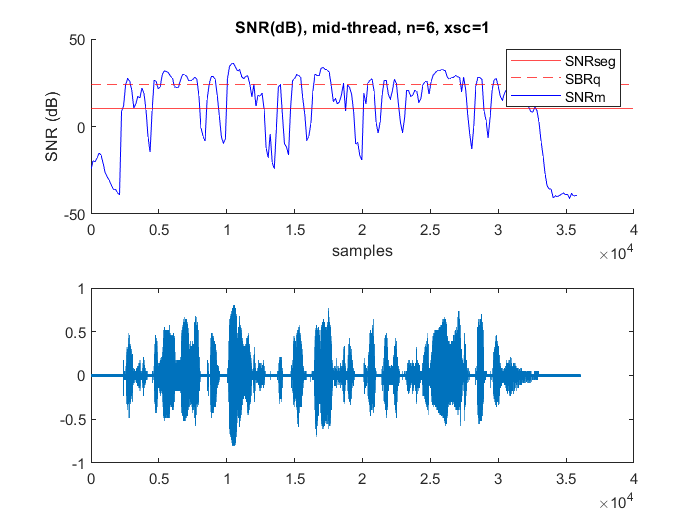

n = 6;
xsc=1;
[Gala_QMR_6b, e_Gala_QMR_6b] = qmidriser(Gala_8kHz, xsc, n);
sound(Gala_QMR_6b);
SNRq = SNR(Gala_8kHz,Gala_QMR_6b);
[SNRseg,SNRm,m] = SNRS(Gala_8kHz,Gala_QMR_6b,150);

%plot (SNRm,SNRq,SNRseg)
figure
subplot 211
hold on
yline(SNRseg,'r')
yline(SNRq,'r--')
plot(m,SNRm,'b')
legend('SNRseg','SBRq','SNRm')
title('SNR(dB), mid-thread, n=6, xsc=1')
hold off

xlabel('samples')
ylabel('SNR (dB)')
subplot 212
plot(Gala_QMR_6b)

`Midtread()`

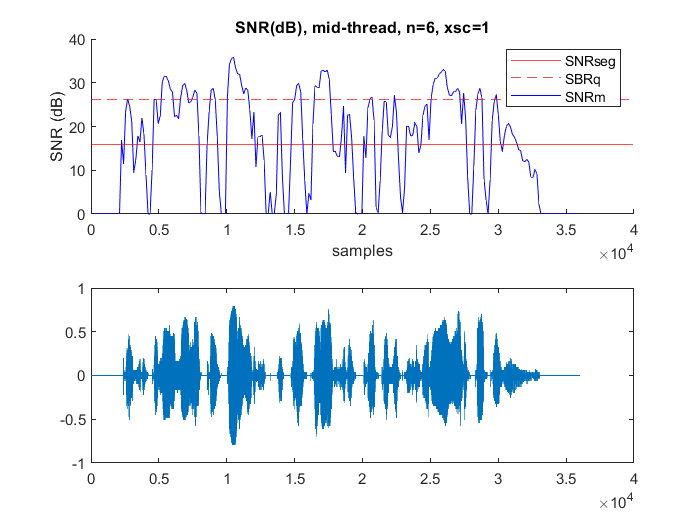

[Gala_QMT_6b, e_Gala_QMT_6b] = qmidtread(Gala_8kHz, xsc, n);
sound(Gala_QMT_6b);
SNRq = SNR(Gala_8kHz,Gala_QMT_6b);
[SNRseg,SNRm,m] = SNRS(Gala_8kHz,Gala_QMT_6b,150);

%plot (SNRm,SNRq,SNRseg)
figure
subplot 211
hold on
yline(SNRseg,'r')
yline(SNRq,'r--')
plot(m,SNRm,'b')
legend('SNRseg','SBRq','SNRm')
title('SNR(dB), mid-thread, n=6, xsc=1')
hold off

xlabel('samples')
ylabel('SNR (dB)')
subplot 212
plot(Gala_QMT_6b)

Repetid el apartado anterior para xsc=0.55 y xsc=0.3. Comparad y comentad los resultados. 

`Midriser()`

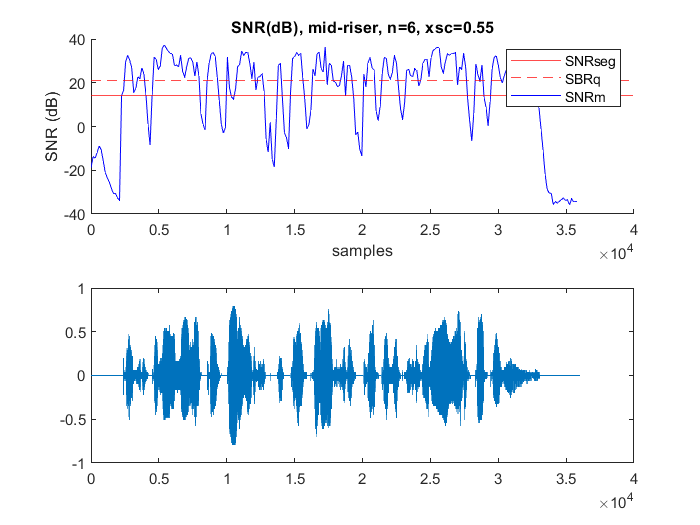

n = 6;
xsc=0.55;
[Gala_QMR_6b, e_Gala_QMR_6b] = qmidriser(Gala_8kHz, xsc, n);
sound(Gala_QMR_6b);
SNRq = SNR(Gala_8kHz,Gala_QMR_6b);
[SNRseg,SNRm,m] = SNRS(Gala_8kHz,Gala_QMR_6b,150);

%plot (SNRm,SNRq,SNRseg)
figure
subplot 211
hold on
yline(SNRseg,'r')
yline(SNRq,'r--')
plot(m,SNRm,'b')
legend('SNRseg','SBRq','SNRm')
hold off

xlabel('samples')
ylabel('SNR (dB)')
title('SNR(dB), mid-riser, n=6, xsc=0.55')
subplot 212
plot(Gala_QMT_6b)

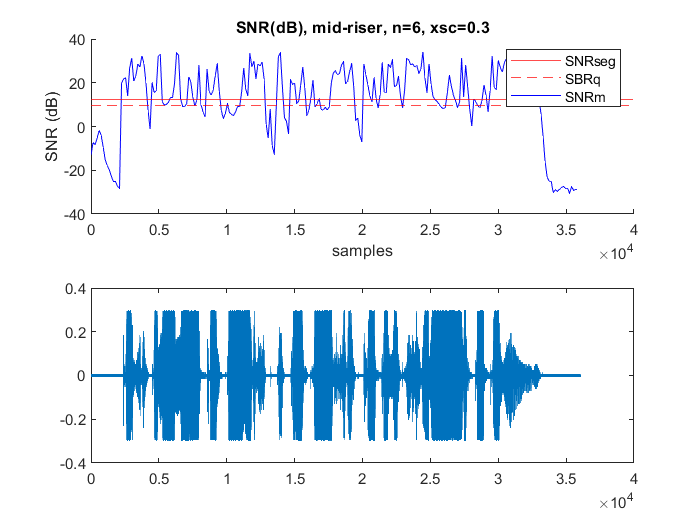


xsc=0.3;
[Gala_QMR_6b, e_Gala_QMR_6b] = qmidriser(Gala_8kHz, xsc, n);
sound(Gala_QMR_6b);
SNRq = SNR(Gala_8kHz,Gala_QMR_6b);
[SNRseg,SNRm,m] = SNRS(Gala_8kHz,Gala_QMR_6b,150);

%plot (SNRm,SNRq,SNRseg)
figure
subplot 211
hold on
yline(SNRseg,'r')
yline(SNRq,'r--')
plot(m,SNRm,'b')
legend('SNRseg','SBRq','SNRm')
hold off

xlabel('samples')
ylabel('SNR (dB)')
title('SNR(dB), mid-riser, n=6, xsc=0.3')
subplot 212
plot(Gala_QMR_6b)

`Midthread()`

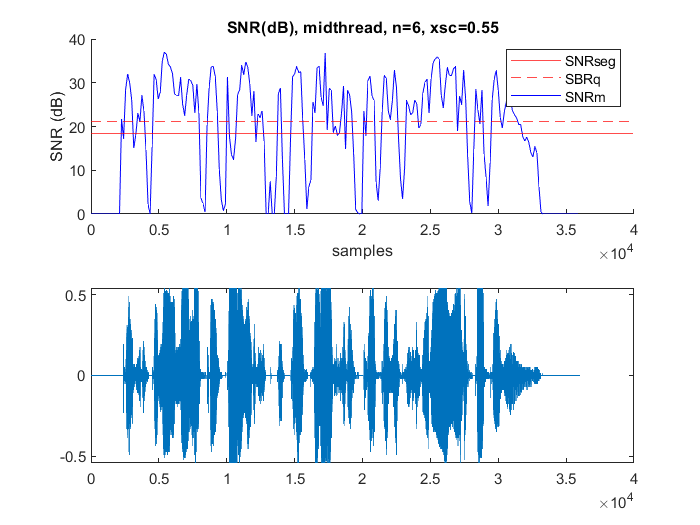

xsc=0.55;
[Gala_QMT_6b, e_Gala_QMT_6b] = qmidtread(Gala_8kHz, xsc, n);
sound(Gala_QMT_6b);
SNRq = SNR(Gala_8kHz,Gala_QMT_6b);
[SNRseg,SNRm,m] = SNRS(Gala_8kHz,Gala_QMT_6b,150);

%plot (SNRm,SNRq,SNRseg)
figure
subplot 211
hold on
yline(SNRseg,'r')
yline(SNRq,'r--')
plot(m,SNRm,'b')
legend('SNRseg','SBRq','SNRm')
hold off

xlabel('samples')
ylabel('SNR (dB)')
title('SNR(dB), midthread, n=6, xsc=0.55')
subplot 212
plot(Gala_QMT_6b)

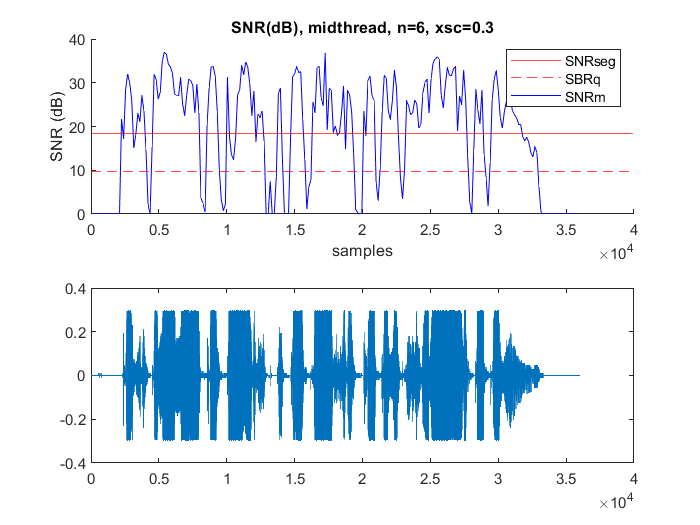


xsc=0.3;
[Gala_QMT_6b, e_Gala_QMT_6b] = qmidtread(Gala_8kHz, xsc, n);
sound(Gala_QMT_6b);
SNRq = SNR(Gala_8kHz,Gala_QMT_6b);

%plot (SNRm,SNRq,SNRseg)
figure
subplot 211
hold on
yline(SNRseg,'r')
yline(SNRq,'r--')
plot(m,SNRm,'b')
legend('SNRseg','SBRq','SNRm')
hold off

xlabel('samples')
ylabel('SNR (dB)')
title('SNR(dB), midthread, n=6, xsc=0.3')
subplot 212
plot(Gala_QMT_6b)

Para los ficheros Gala_8kHz.wav e Afonso_8kHz.wav, con n=1:8, xsc=1. 

- Obtened la SNR global en todos los casos, considerando qmidriser() y qmidtread(). 

- Representad resultados como en la gráfica de la diapositiva “Ejemplo 3”. 

`Midriser()`

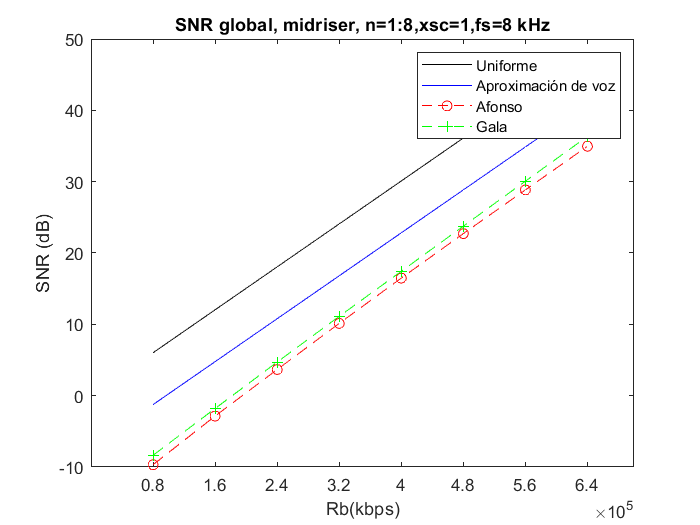

xsc=1;
for n=1:1:8
    [Afonso_QMR_nb, e_Afonso_QMR_nb] = qmidriser(Afonso_8kHz, xsc, n);
    sound(Afonso_QMR_nb);
    SNRq_A(1,n) = SNR(Afonso_8kHz,Afonso_QMR_nb);
    [SNRseg_A,SNRm_A,m_A] = SNRS(Afonso_8kHz,Afonso_QMR_nb,150);   
end
for n=1:1:8
    [Gala_QMR_nb, e_Gala_QMR_nb] = qmidriser(Gala_8kHz, xsc, n);
    sound(Gala_QMR_nb);
    SNRq_G(1,n) = SNR(Gala_8kHz,Gala_QMR_nb);
    [SNRseg_G,SNRm_G,m_G] = SNRS(Gala_8kHz,Gala_QMR_nb,150);   
end
n=1:1:8;
Rb = 8*10^4*n;
figure
plot(Rb,6.02*n,'k')
hold on;
plot(Rb,6.02*n-7.27,'b')
hold on;
plot(Rb,SNRq_A,'r--o');
ax = gca; 
ax.XTick = Rb; 
grid
hold on;plot(Rb,SNRq_G,'g--+');
ax = gca; 
ax.XTick = Rb; 
xlabel('Rb(kbps)')
ylabel('SNR (dB)')
legend('Uniforme','Aproximación de voz', 'Afonso', 'Gala')
title("SNR global, midriser, n=1:8,xsc=1,fs=8 kHz")
grid

`Midtread()`

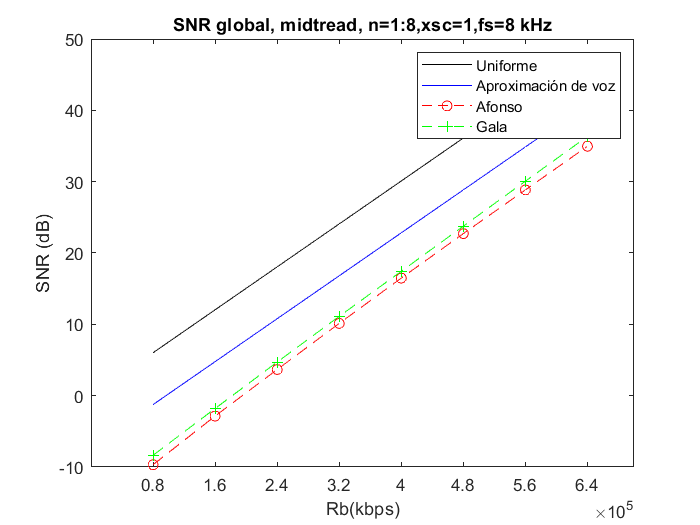

xsc=1;
for n=1:1:8
    [Afonso_QMT_nb, e_Afonso_QMT_nb] = qmidriser(Afonso_8kHz, xsc, n);
    sound(Afonso_QMT_nb);
    SNRq_A(1,n) = SNR(Afonso_8kHz,Afonso_QMT_nb);
    [SNRseg_A,SNRm_A,m_A] = SNRS(Afonso_8kHz,Afonso_QMT_nb,150);   
end
for n=1:1:8
    [Gala_QMT_nb, e_Gala_QMT_nb] = qmidriser(Gala_8kHz, xsc, n);
    sound(Gala_QMR_nb);
    SNRq_G(1,n) = SNR(Gala_8kHz,Gala_QMT_nb);
    [SNRseg_G,SNRm_G,m_G] = SNRS(Gala_8kHz,Gala_QMT_nb,150);   
end
n=1:1:8;
Rb = 8*10^4*n;
figure
plot(Rb,6.02*n,'k')
hold on;
plot(Rb,6.02*n-7.27,'b')
hold on;
plot(Rb,SNRq_A,'r--o');
ax = gca; 
ax.XTick = Rb; 
grid
hold on;plot(Rb,SNRq_G,'g--+');
ax = gca; 
ax.XTick = Rb; 
xlabel('Rb(kbps)')
ylabel('SNR (dB)')
legend('Uniforme','Aproximación de voz', 'Afonso', 'Gala')
title("SNR global, midtread, n=1:8,xsc=1,fs=8 kHz")
grid

- Repetid para n=1:8, xsc=0.55 y xsc=0.3. En este apartado sólo con qmidriser(). 

- Explicad los resultados obtenidos. 

`Midriser()`

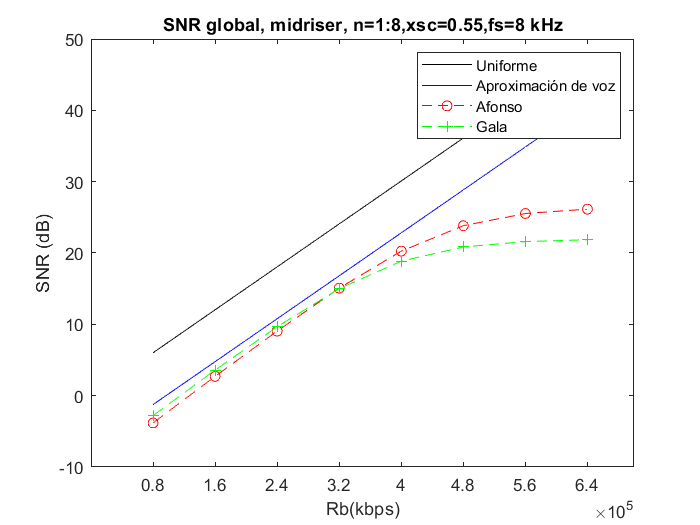

xsc=0.55;
for n=1:1:8
    [Afonso_QMR_nb, e_Afonso_QMR_nb] = qmidriser(Afonso_8kHz, xsc, n);
    sound(Afonso_QMR_nb);
    SNRq_A(1,n) = SNR(Afonso_8kHz,Afonso_QMR_nb);
    [SNRseg_A,SNRm_A,m_A] = SNRS(Afonso_8kHz,Afonso_QMR_nb,150);   
end
for n=1:1:8
    [Gala_QMR_nb, e_Gala_QMR_nb] = qmidriser(Gala_8kHz, xsc, n);
    sound(Gala_QMR_nb);
    SNRq_G(1,n) = SNR(Gala_8kHz,Gala_QMR_nb);
    [SNRseg_G,SNRm_G,m_G] = SNRS(Gala_8kHz,Gala_QMR_nb,150);   
end
n=1:1:8;
Rb = 8*10^4*n;
figure
plot(Rb,6.02*n,'k')
hold on;
plot(Rb,6.02*n-7.27,'b')
hold on;
plot(Rb,SNRq_A,'r--o');
ax = gca; 
ax.XTick = Rb; 
grid
hold on;plot(Rb,SNRq_G,'g--+');
ax = gca; 
ax.XTick = Rb; 
xlabel('Rb(kbps)')
ylabel('SNR (dB)')
legend('Uniforme','Aproximación de voz', 'Afonso', 'Gala')
title("SNR global, midriser, n=1:8,xsc=0.55,fs=8 kHz")
grid

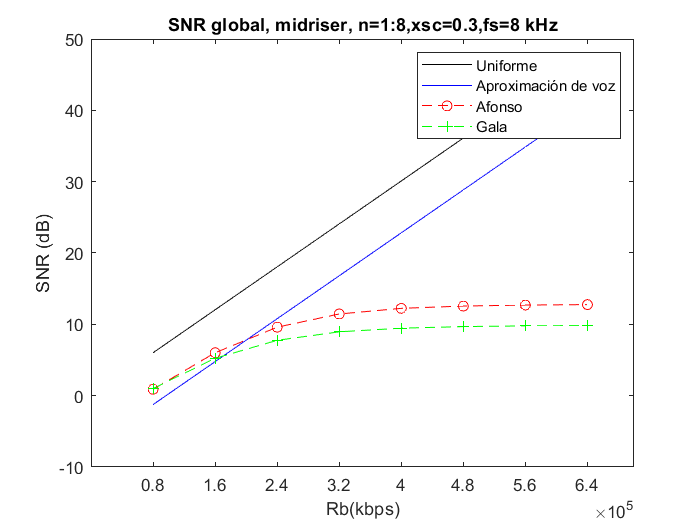

xsc=0.3;
for n=1:1:8
    [Afonso_QMT_nb, e_Afonso_QMT_nb] = qmidriser(Afonso_8kHz, xsc, n);
    sound(Afonso_QMT_nb);
    SNRq_A(1,n) = SNR(Afonso_8kHz,Afonso_QMT_nb);
    [SNRseg_A,SNRm_A,m_A] = SNRS(Afonso_8kHz,Afonso_QMT_nb,150);   
end
for n=1:1:8
    [Gala_QMT_nb, e_Gala_QMT_nb] = qmidriser(Gala_8kHz, xsc, n);
    sound(Gala_QMR_nb);
    SNRq_G(1,n) = SNR(Gala_8kHz,Gala_QMT_nb);
    [SNRseg_G,SNRm_G,m_G] = SNRS(Gala_8kHz,Gala_QMT_nb,150);   
end
n=1:1:8;
Rb = 8*10^4*n;
figure
plot(Rb,6.02*n,'k')
hold on;
plot(Rb,6.02*n-7.27,'b')
hold on;
plot(Rb,SNRq_A,'r--o');
ax = gca; 
ax.XTick = Rb; 
grid
hold on;plot(Rb,SNRq_G,'g--+');
ax = gca; 
ax.XTick = Rb; 
xlabel('Rb(kbps)')
ylabel('SNR (dB)')
legend('Uniforme','Aproximación de voz', 'Afonso', 'Gala')
title("SNR global, midriser, n=1:8,xsc=0.3,fs=8 kHz")
grid